# Measurement of g and Drag Forces on Falling Balls

By dropping a steel and nylon ball from a series of heights, we aim to experimentally determine the acceleration due to gravity, g.

**Uncertainty in time and distance measurements**

Time error for nylon: 139 us 
Time error for steel: 118 us 
Distance error: 20 um 
Time error: 140 us 
y/t error: 778 um/us to 994 um/us


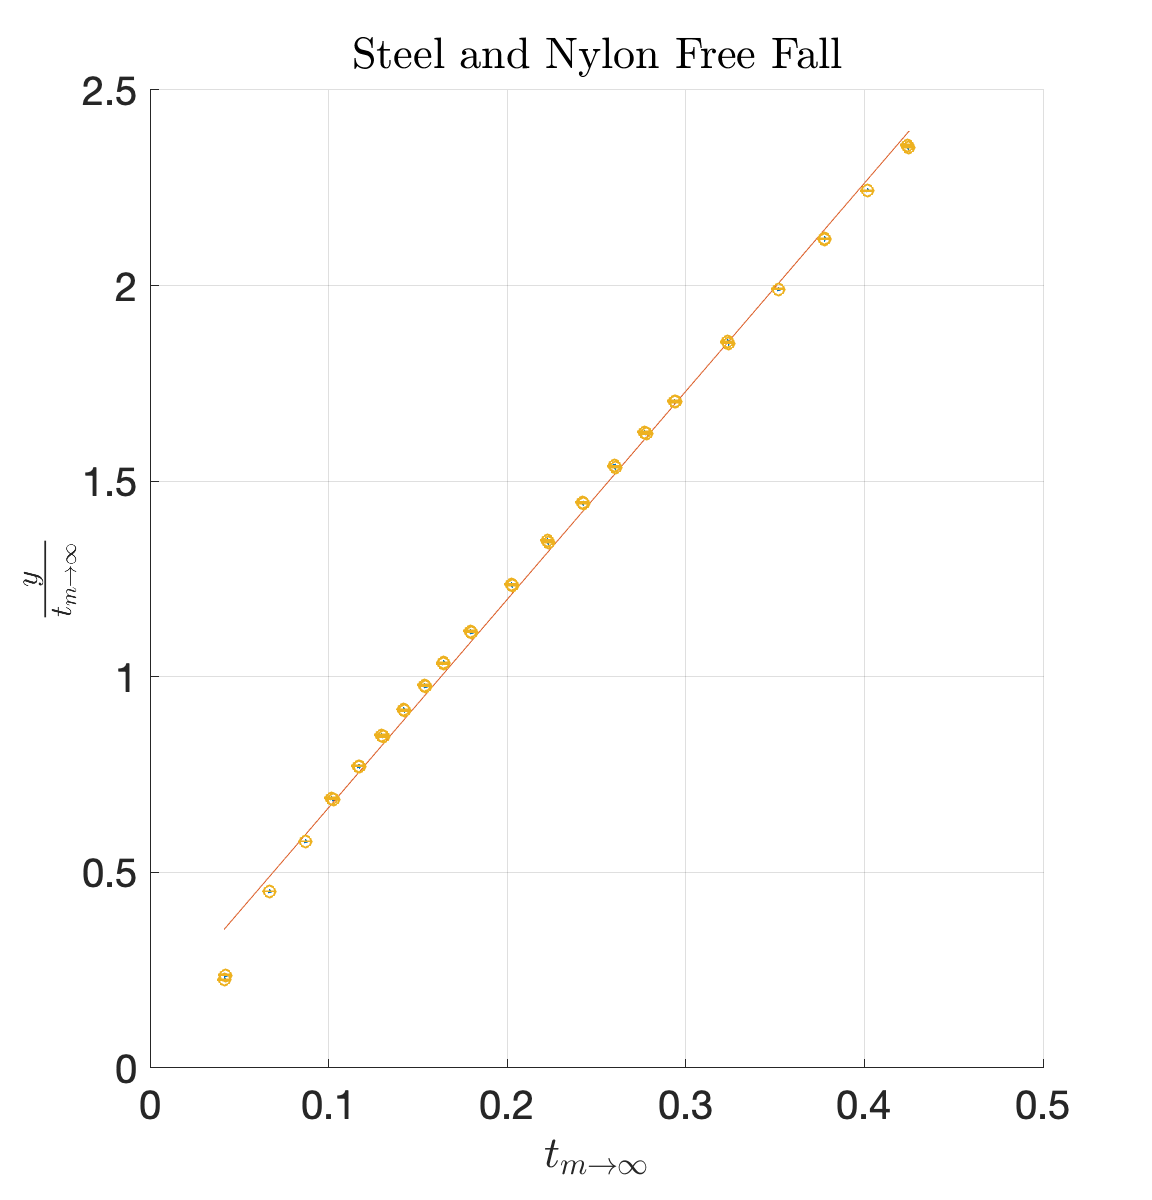

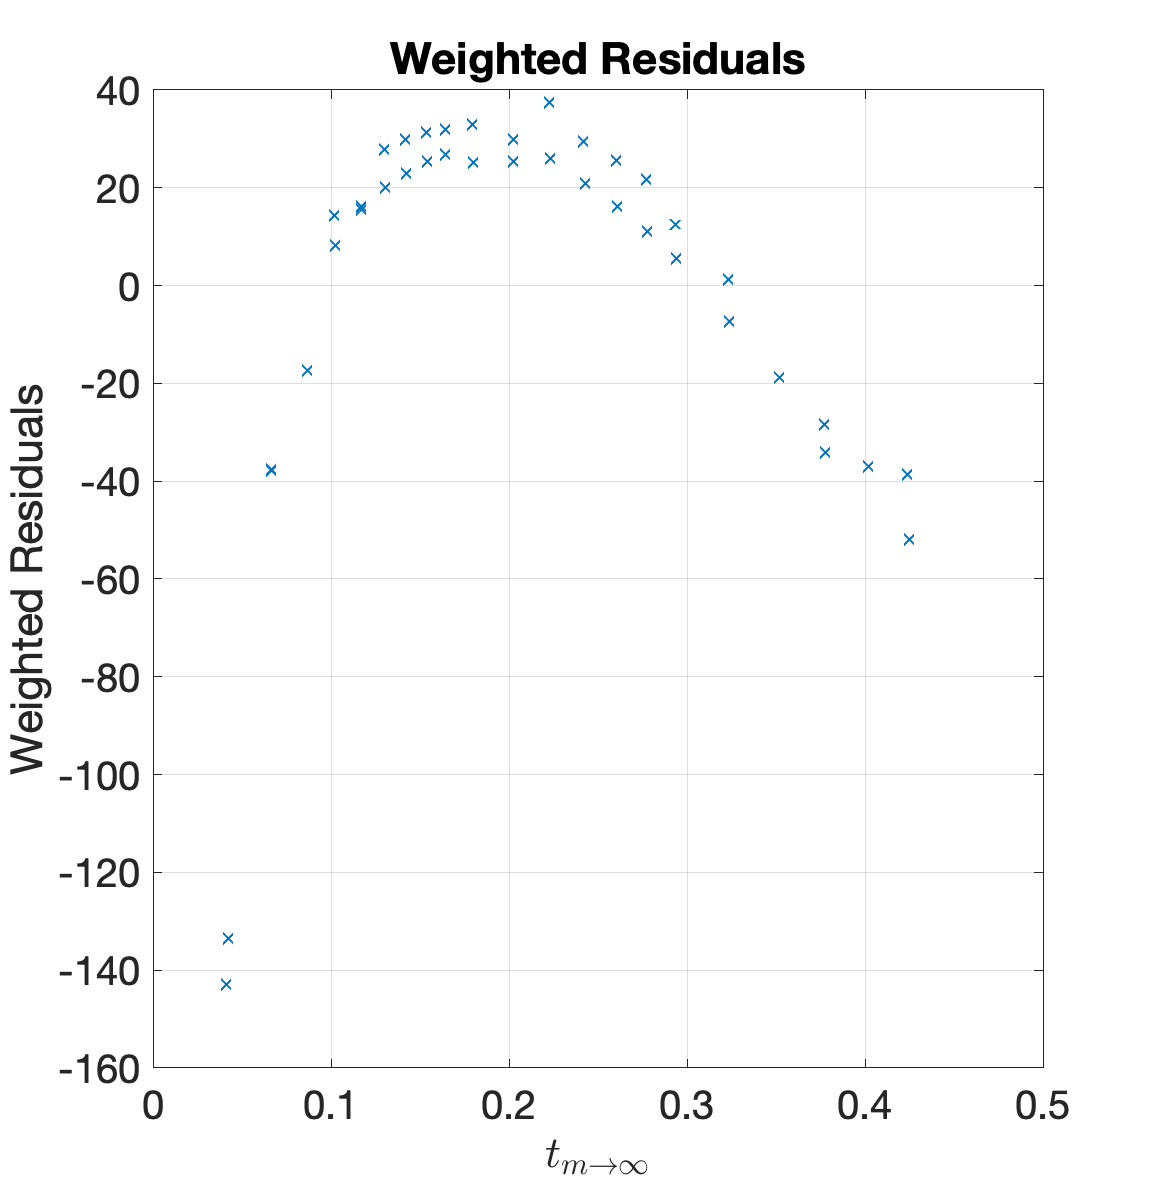

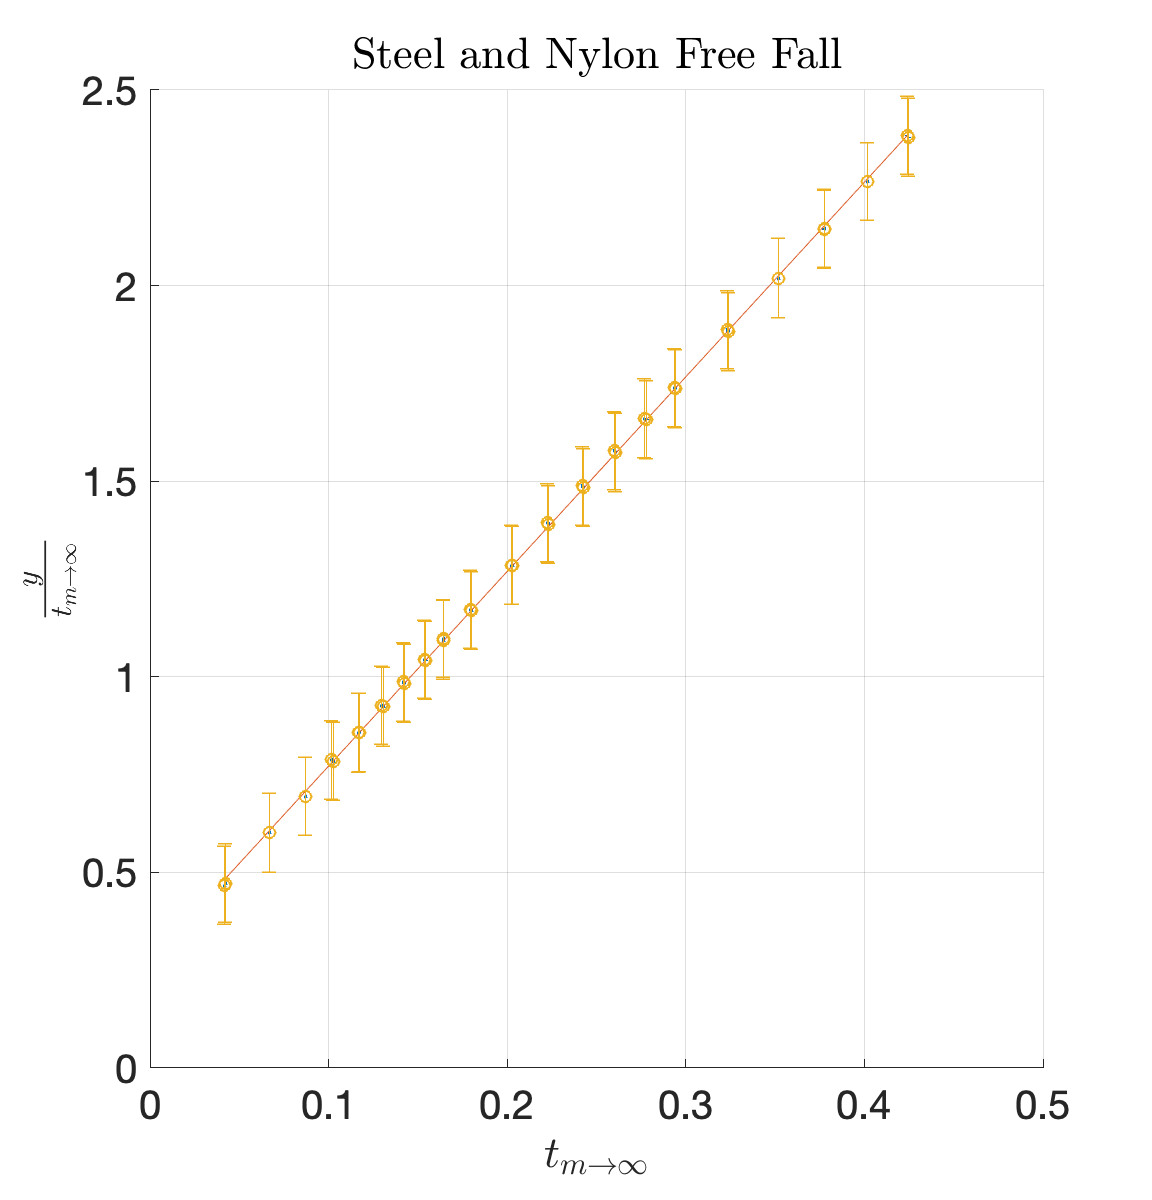

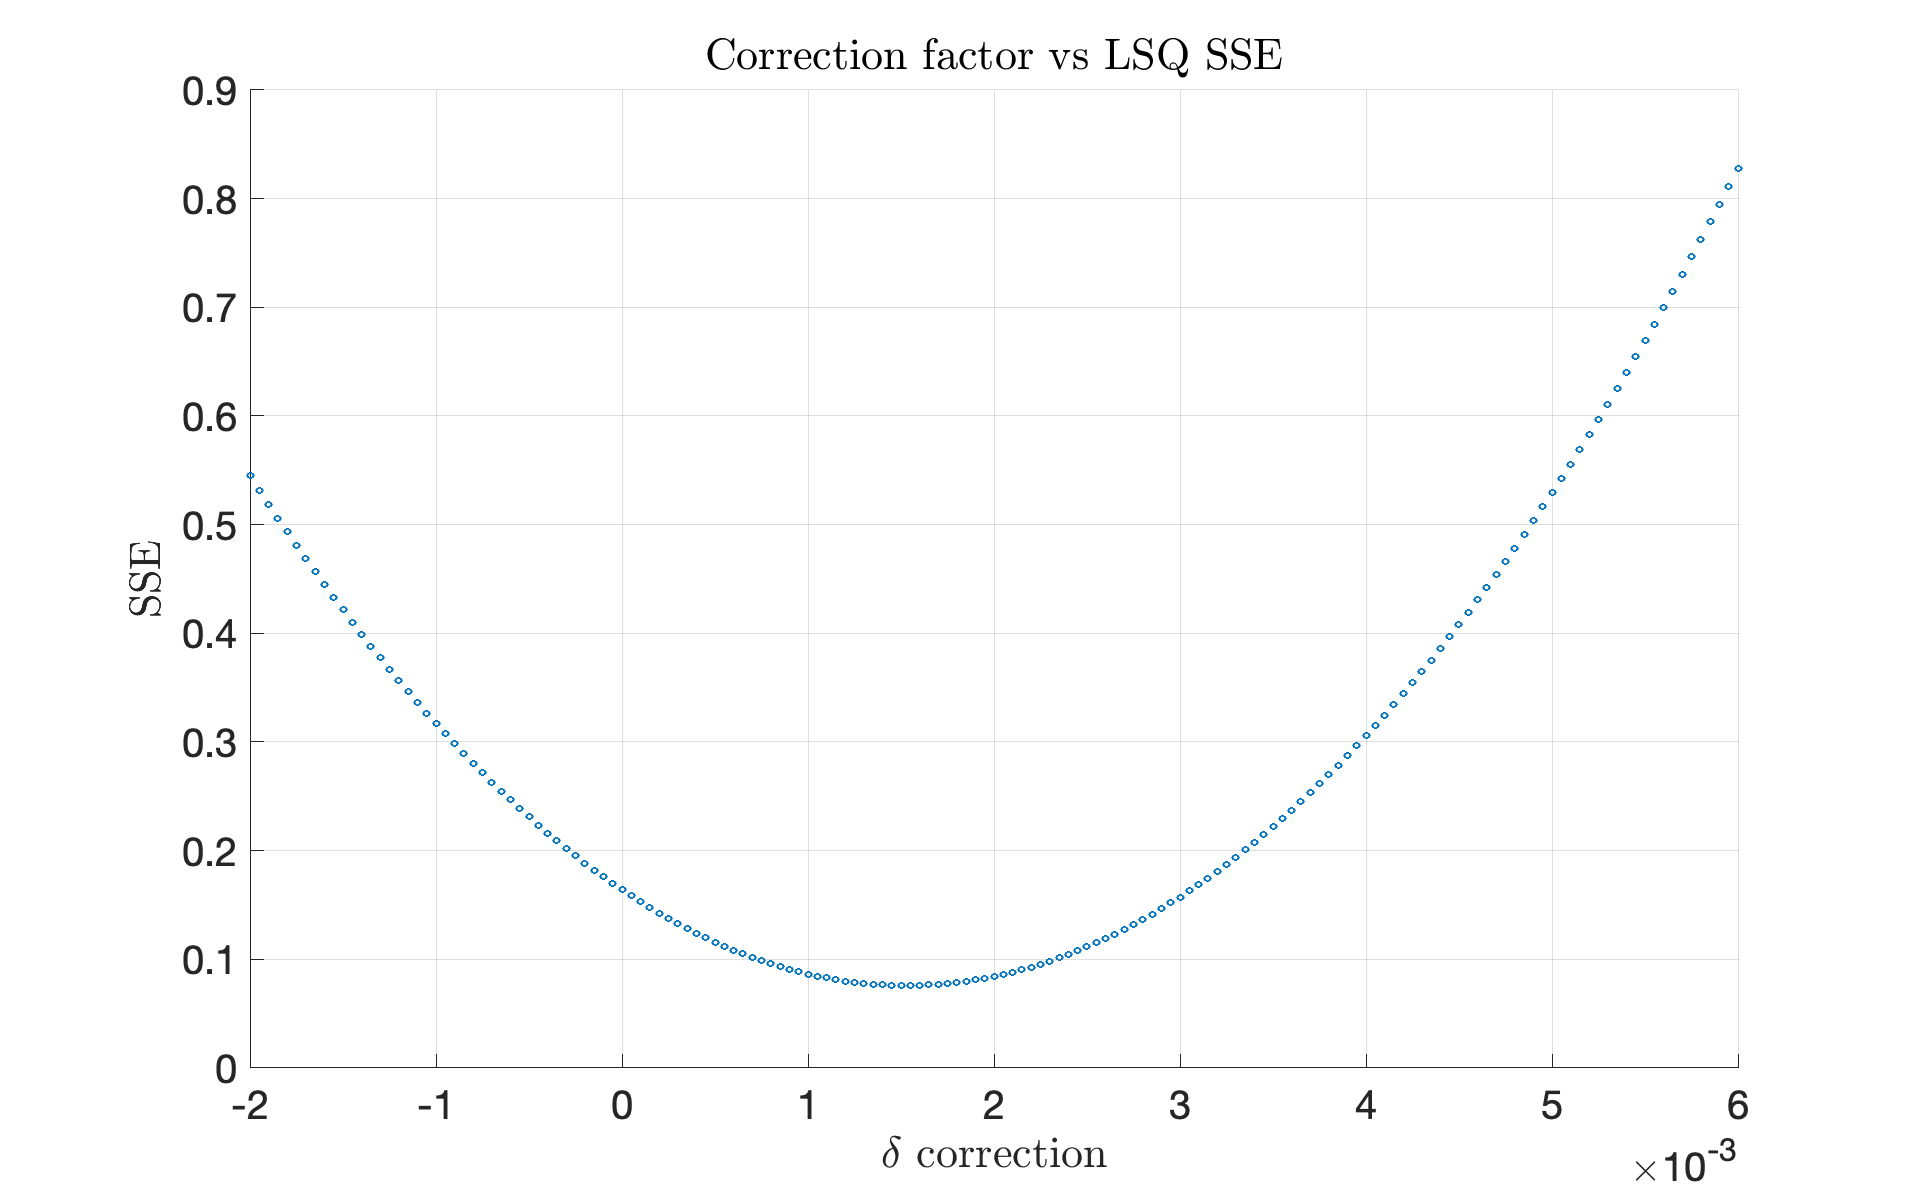

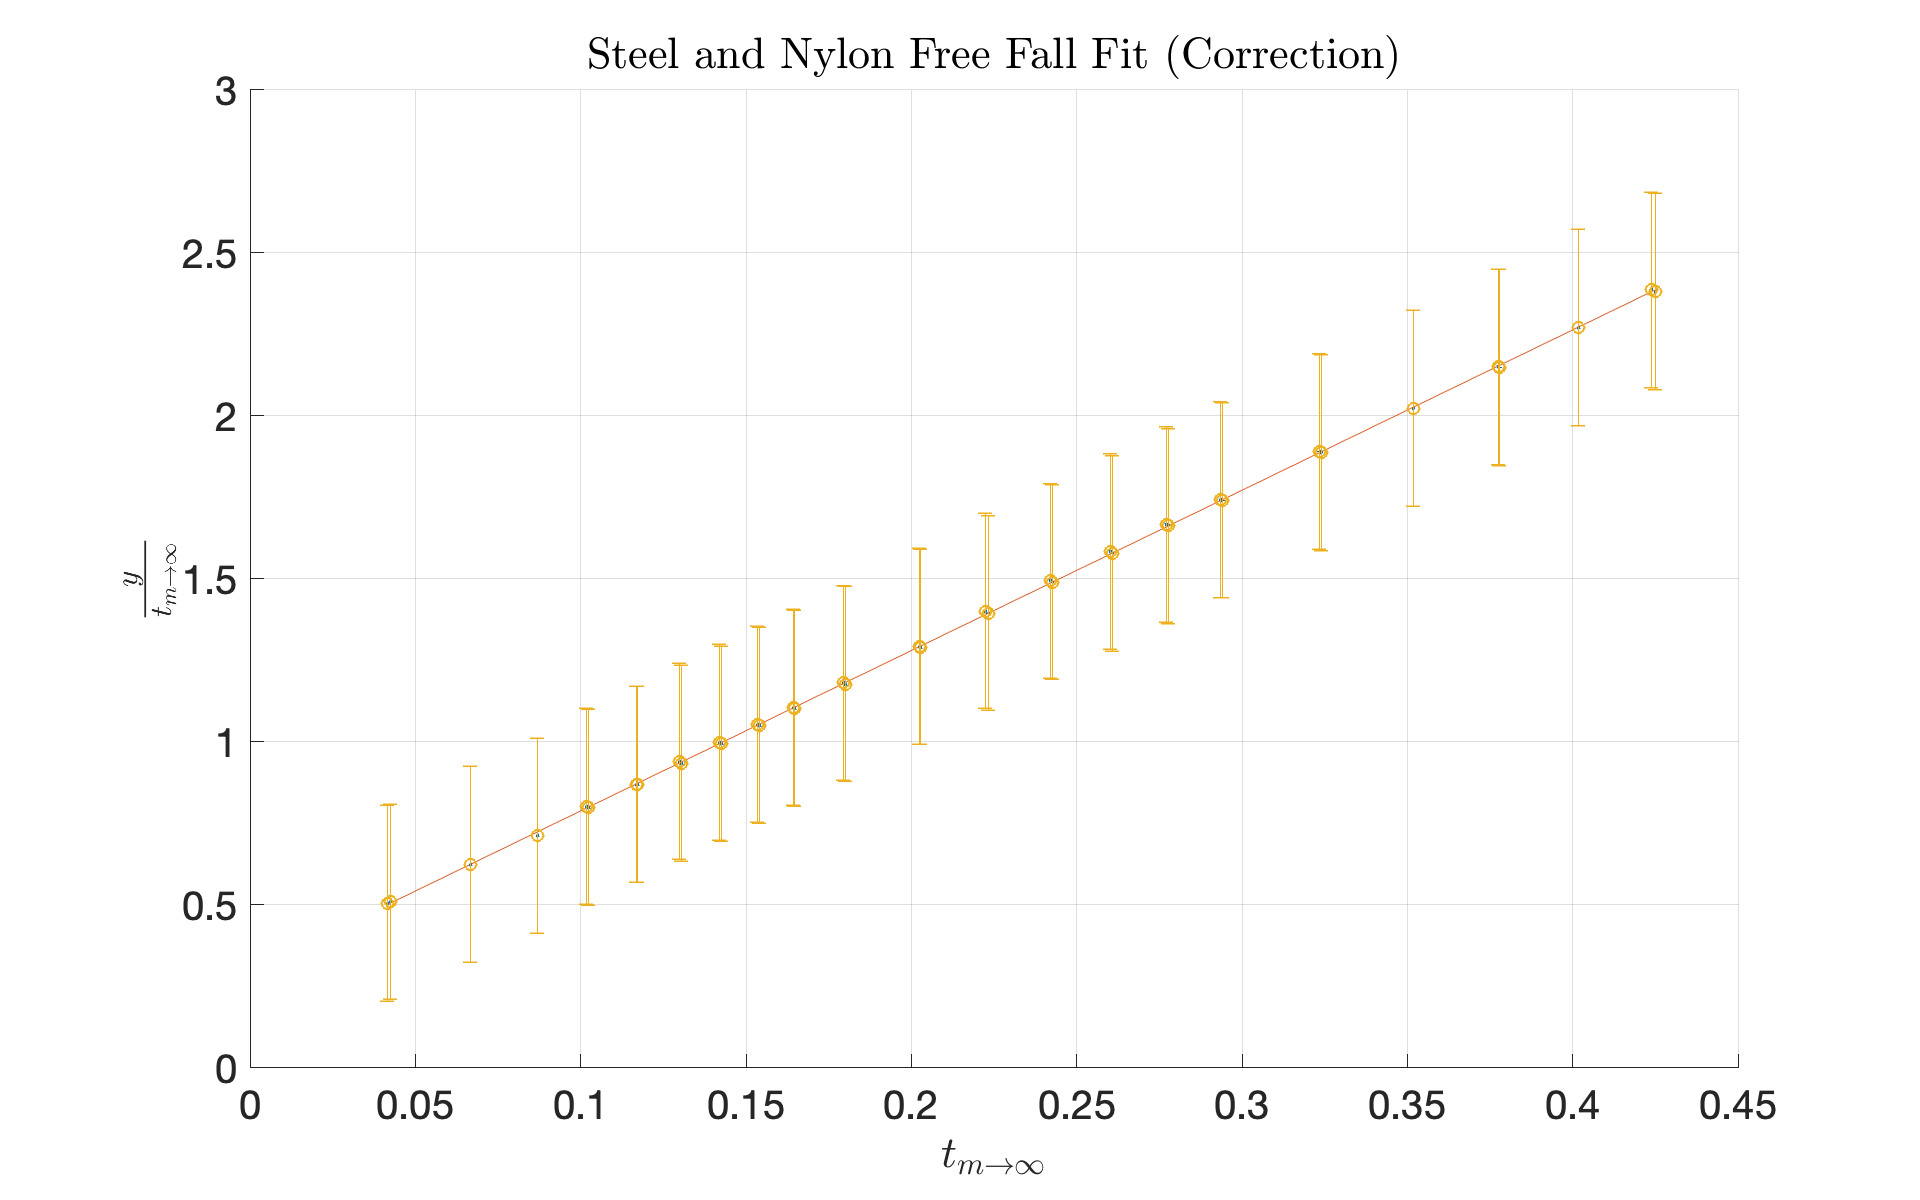

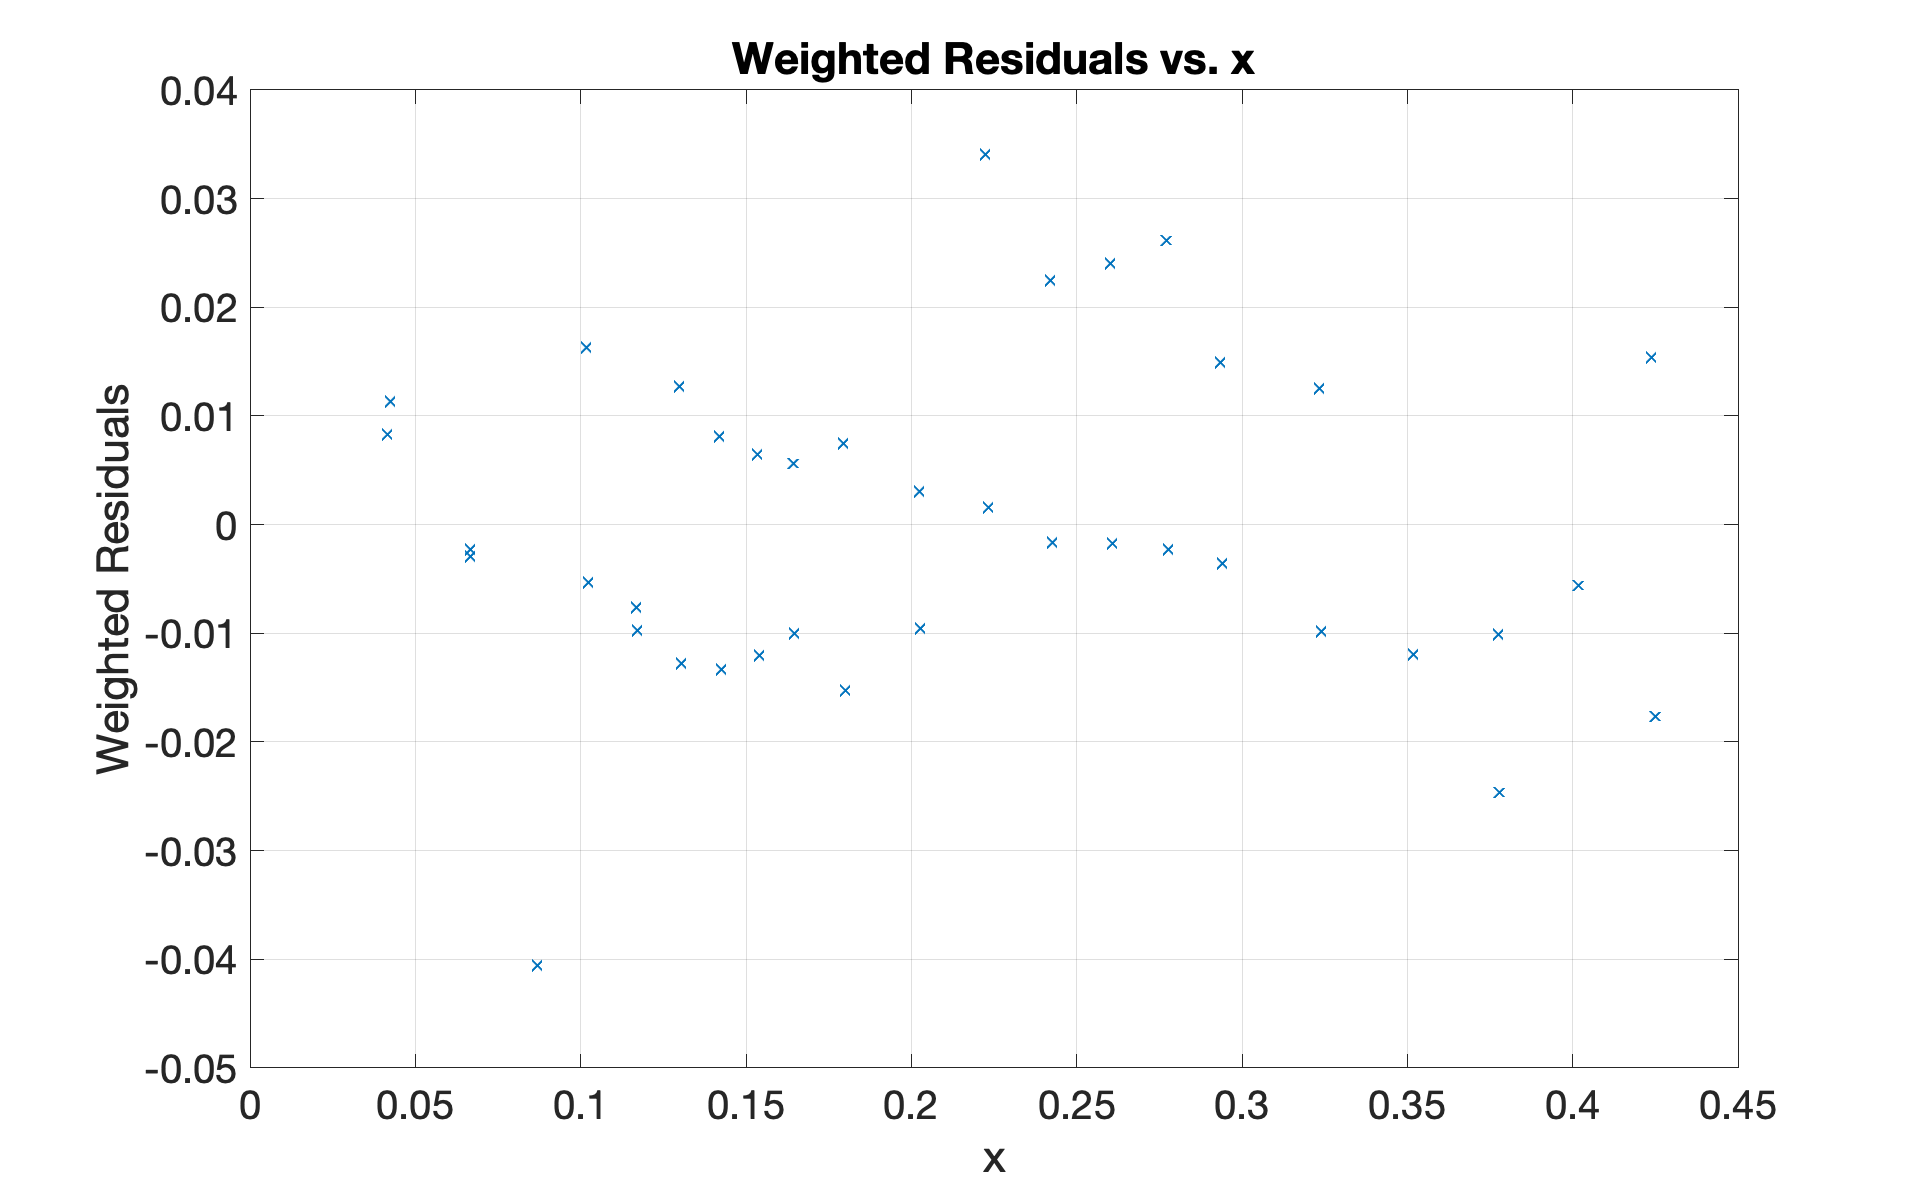



Best Value of del is: del = 0.00155


Sum of Chi Squared = 0.076 


Reduced Chi Squared = 0.000 


Calculated value of g = 9.83585 +/- 0.89551 m/s^2 


Calculated value of V0 = 0.29688 +/- 0.10660 m/s 


close all

clear all
% Height for time measurements = 500.22 +/- 0.01 mm
data = dlmread('Time Measurements.csv',',',1,0);
t_nylon = data(:,1);
t_steel = data(:,2);
% Time resolution of the meter PM2525 is 10 micro seconds
t_nylon_err = std(t_nylon);
t_steel_err = std(t_steel);

data = dlmread('Ball Dropper Data.csv',',',2,5);
y = data(:,1)./1000; % drop heights (meters)
y_err = data(:,2)./1000; % meters
t_nylon = data(:,3);% seconds
t_steel = data(:,4);% seconds
m_nylon = 0.00409; % kg
m_steel = 0.02817; % kg

delete = [4,24,41];
[t_nylon,t_steel,y,y_err] = drop(delete,t_nylon,t_steel,y,y_err);

t_inf = (t_steel*m_steel- t_nylon*m_nylon)./(m_steel-m_nylon);
t_inf_err = 1/(m_steel-...
    m_nylon).*sqrt((m_steel.*t_steel_err).^2+....
    (m_nylon.*t_nylon_err).^2);

dydt = y./t_inf;
dydt_err = sqrt(t_inf_err^2.*(y./t_inf.^2).^2+...
                y_err.^2.*(1./t_inf).^2);
fprintf(['Time error for nylon: %.0f us \n'...  
         'Time error for steel: %.0f us \n'...
         'Distance error: %.0f um \nTime error: %.0f us \n'...
         'y/t error: %.0f um/us to %.0f um/us\n'],...
          t_nylon_err*10^6,t_steel_err*10^6,y_err(1)*10^6,...
          t_inf_err*10^6,min(dydt_err)*10^6,max(dydt_err*10^6));
      
[fitobj, gof, outp] = fit(t_inf, dydt,'poly1','Weights',...
    (1./dydt_err).^2);
yplot = fitobj.p1.*t_inf+fitobj.p2;

figure(1)
set(gcf,'Units','Normalized','Position',[0.35 0.5 0.3 0.5])
scatter(t_inf,dydt,2)
hold on
plot(t_inf,yplot)
xlabel('$t_{m \rightarrow \infty}$','Interpreter','latex')
ylabel('$\frac{y}{t_{m \rightarrow \infty}}$',...
    'Interpreter','latex')
title('Steel and Nylon Free Fall',...
'Interpreter','latex')
set(gca,'FontSize',20)   
grid on
errorbar(t_inf,dydt,dydt_err,'o');
hold off

figure(2)
set(gcf,'Units','Normalized','Position',[0.65 0.5 0.3 0.5])
plot(t_inf(1:length(outp.residuals),:), (outp.residuals), 'x')
title('Weighted Residuals')
xlabel('$t_{m \rightarrow \infty}$','Interpreter','latex')
ylabel('Weighted Residuals')
set(gca,'FontSize',20) 
grid on

%% ESTIMATE OF B

b = 0.01; % m
b_err = 0.001; 
dydt = (y+b)./t_inf;
dydt_err = sqrt(t_inf_err^2.*((y+b)./t_inf.^2).^2+...
                y_err.^2.*(1./t_inf).^2 + ...
                b_err.^2.*(1./b).^2);

    
[fitobj, gof, outp] = fit(t_inf, dydt,'poly1','Weights',(1./dydt_err).^2);
yplot2 = fitobj.p1.*t_inf+fitobj.p2;
figure(3)
set(gcf,'Units','Normalized','Position',[0.35 0.5 0.3 0.5])
scatter(t_inf,dydt,2)
hold on
plot(t_inf,yplot2)
xlabel('$t_{m \rightarrow \infty}$','Interpreter','latex')
ylabel('$\frac{y}{t_{m \rightarrow \infty}}$',...
    'Interpreter','latex')
title('Steel and Nylon Free Fall',...
'Interpreter','latex')
set(gca,'FontSize',20)   
grid on
errorbar(t_inf,dydt,dydt_err,'o');
hold off

del = (-0.002:0.00005:0.006)';
sse = zeros(length(del),1);
for i = 1:length(del)
    del_0 = del(i);
    dydt = (y+b)./t_inf + del_0./t_inf;   
    dydt_err = sqrt(t_inf_err^2.*((y+b)./t_inf.^2).^2+...
                y_err.^2.*(1./t_inf).^2 + ...
                b_err.^2.*(1./b).^2);   
    sse(i) = getSSE(t_inf,dydt,dydt_err,del_0);
    
end
figure(4)
set(gcf,'Units','Normalized','Position',[0.65 0.5 0.5 0.5])
scatter(del,sse,10)
xlabel('$\delta$ correction','Interpreter','latex')
ylabel('SSE','Interpreter','latex')
title('Correction factor vs LSQ SSE','Interpreter','latex')
set(gca,'FontSize',20) 
grid on

sse = -1.*sse;
[px,py] = findpeaks(sse,del);
del_best = py;

%% FINAL CALCULATION
% b = b+del_best;
b_err = 3*10^-3;
dydt = (y+b+del_best)./t_inf ;
% dydt = (y+b)./t_inf + del_best./t_inf;
dydt_err = sqrt(t_inf_err^2.*((y+b)./t_inf.^2).^2+...
                y_err.^2.*(1./t_inf).^2 + ...
                b_err.^2.*(1./b).^2);   

p = getparams(t_inf,dydt,dydt_err,del_best);
yp = p.b.*t_inf + p.a;

figure(5)
set(gcf,'Units','Normalized','Position',[0.5 0.05 0.5 0.5])
scatter(t_inf,dydt,2)
hold on
plot(t_inf,yp)
xlabel('$t_{m \rightarrow \infty}$','Interpreter','latex')
ylabel('$\frac{y}{t_{m \rightarrow \infty}}$',...
    'Interpreter','latex')
title('Steel and Nylon Free Fall Fit (Correction)',...
    'Interpreter','latex')
set(gca,'FontSize',20) 
grid on
errorbar(t_inf,dydt,dydt_err,'o');
hold off

figure(6)
set(gcf,'Units','Normalized','Position',[0.65 0.5 0.5 0.5])
plot(t_inf(1:length(p.res),:), (p.res), 'x')
title('Weighted Residuals vs. x')
xlabel('x')
ylabel('Weighted Residuals')
set(gca,'FontSize',20) 
grid on

fprintf('\n\nBest Value of del is: del = %.5f\n',py)
fprintf('Sum of Chi Squared = %.3f \n',-px) 
fprintf('Reduced Chi Squared = %.3f \n',p.r_chi)
fprintf('Calculated value of g = %.5f +/- %.5f m/s^2 \n',2*p.b,2*p.b_err)
fprintf('Calculated value of V0 = %.5f +/- %.5f m/s \n',p.a,p.a_err)

**Finding the "best" value of b (see fig 2.2)**

Freefall equation: $y(t)=v_{0} t+\frac{1}{2} g t^{2}$

Since ball is dropped a distance *b above y(0) : *$y(t)=r(t)+b$

But we have no idea what the exact value of *b *is 

Add an error term $\delta$ :   $b^{\prime}=b+\delta$

$\frac{r(t)+b^{\prime}}{t}=\frac{r(t)+b+\delta}{t}=v_{0}+\frac{1}{2} g t+\frac{\delta}{t}$       where   $\sigma_{\frac{y}{t}}=\sqrt{\sigma_{t}^{2}\left(\frac{y}{2}\right)^{2}+\sigma_{y}^{2}\left(\frac{1}{t}\right)^{2}}$


$$\sigma_{\frac{y}{t}}^{2}=\sigma_{y}^{2}\left(\frac{\partial\left(\frac{y}{t} \right)}{\partial y}\right)^{2}+\sigma_{t}^{2} \left(\frac{\partial\left(\frac{y}{t}\right)}{\partial t}\right)^{2}$$


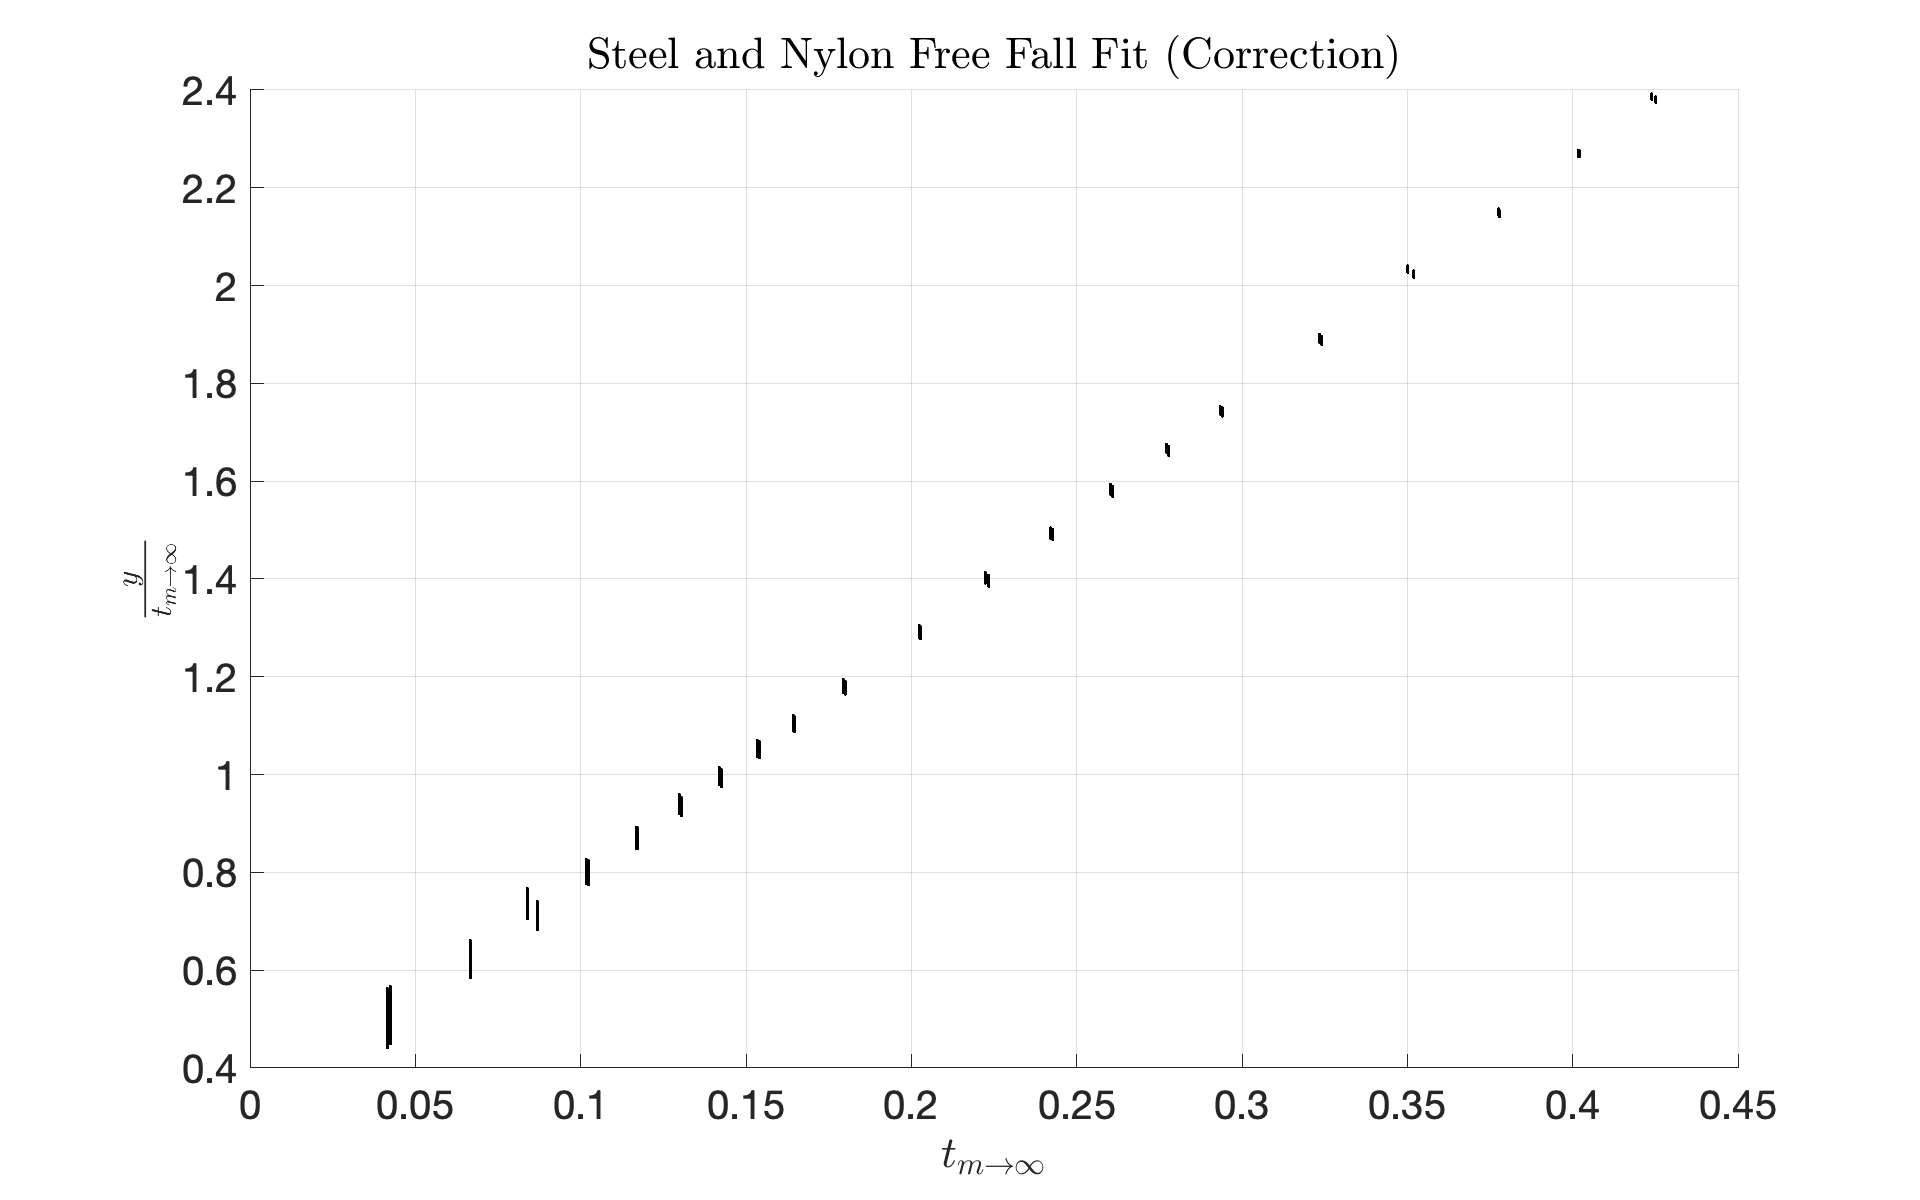

del = (0.009:0.00002:0.014)';
sse = zeros(length(del),1);

figure(3)
set(gcf,'Units','Normalized','Position',[0.35 0.5 0.5 0.5])
hold on
for i = 1:length(del)
    del_0 = del(i);
    dydt = y./t_inf + del_0./t_inf;
    sse(i) = getSSE(t_inf,dydt,dydt_err,del_0);
    scatter(t_inf,dydt,0.3,'black')
end
xlabel('$t_{m \rightarrow \infty}$','Interpreter','latex')
ylabel('$\frac{y}{t_{m \rightarrow \infty}}$',...
    'Interpreter','latex')
title('Steel and Nylon Free Fall Fit (Correction)',...
    'Interpreter','latex')
set(gca,'FontSize',20) 
grid on
hold off

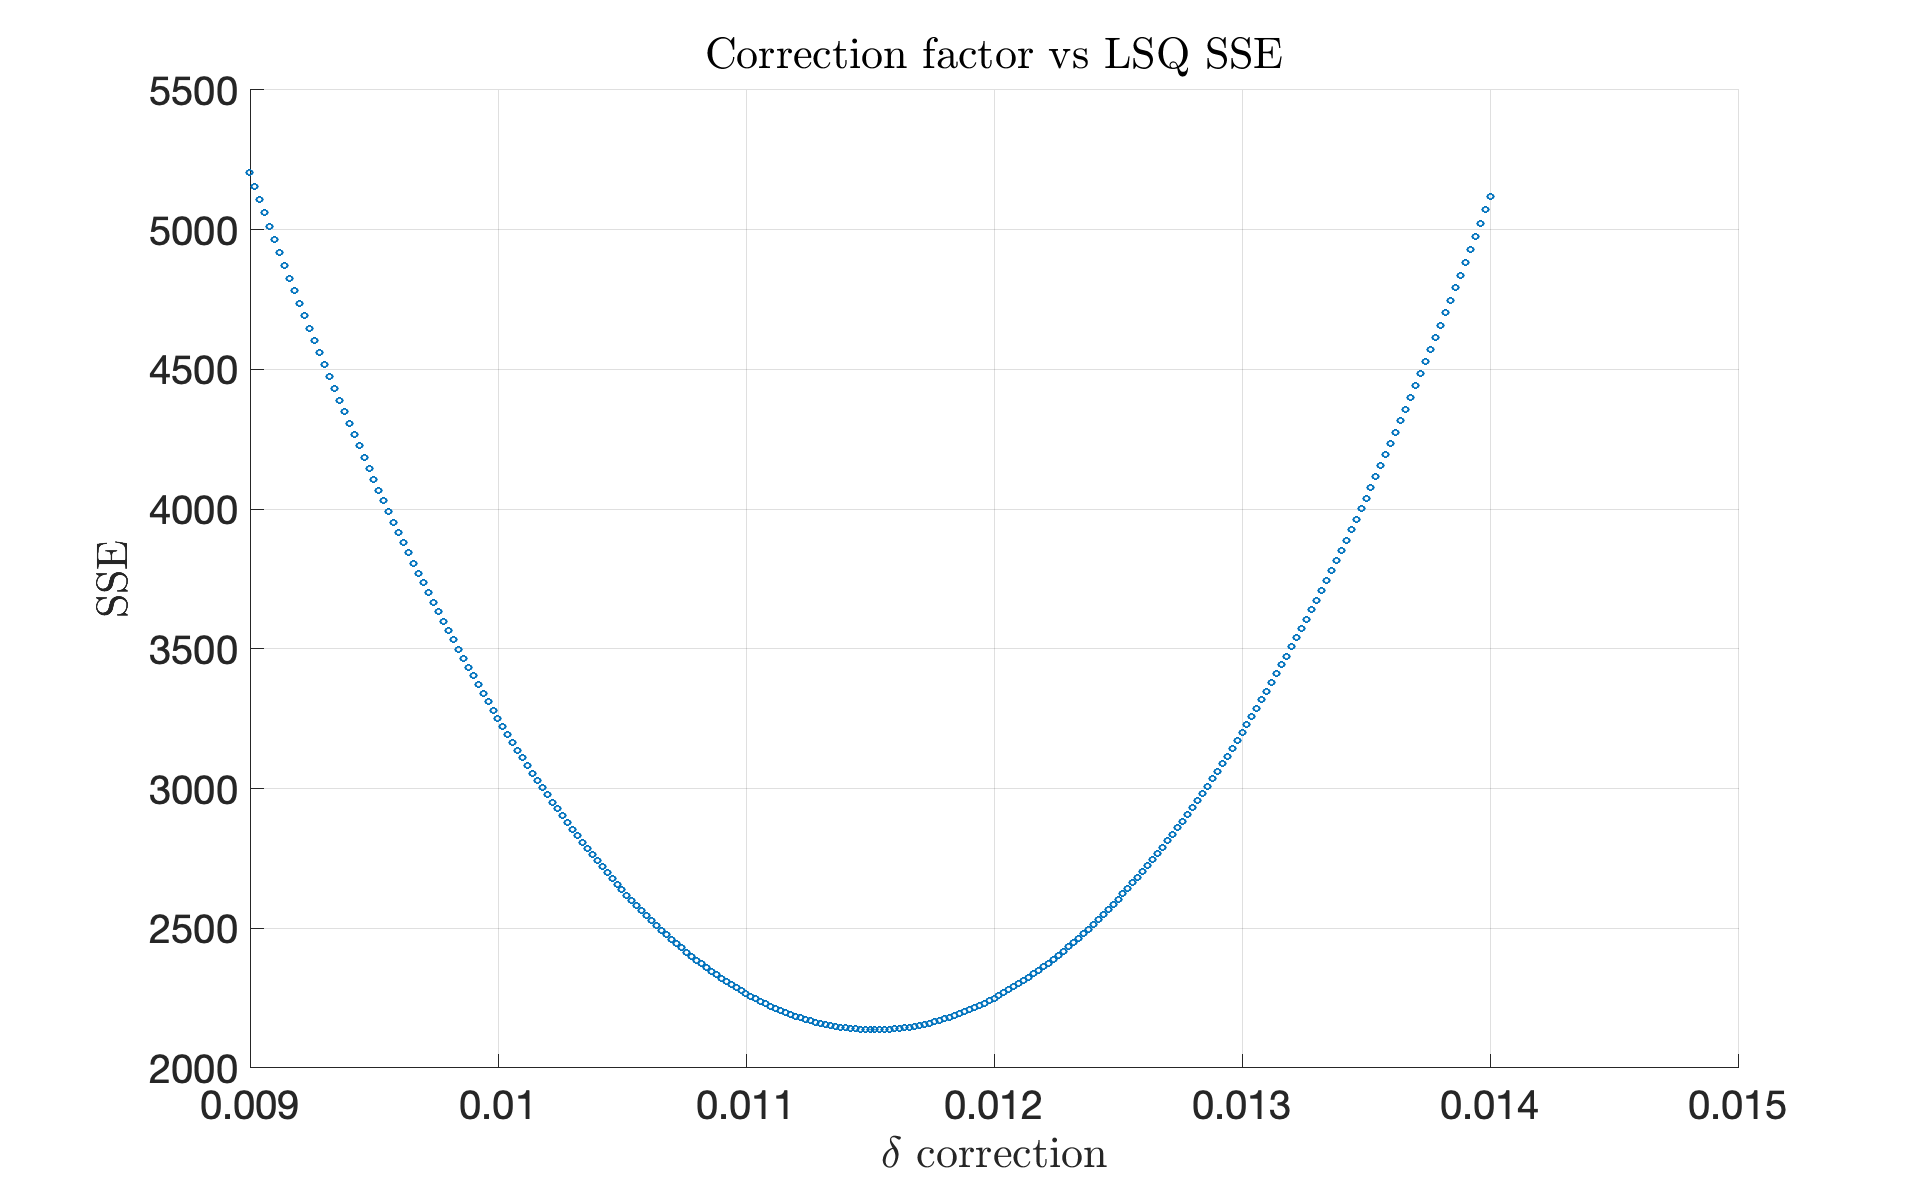


figure(4)
set(gcf,'Units','Normalized','Position',[0.65 0.5 0.5 0.5])
scatter(del,sse,10)
xlabel('$\delta$ correction','Interpreter','latex')
ylabel('SSE','Interpreter','latex')
title('Correction factor vs LSQ SSE','Interpreter','latex')
set(gca,'FontSize',20) 
grid on

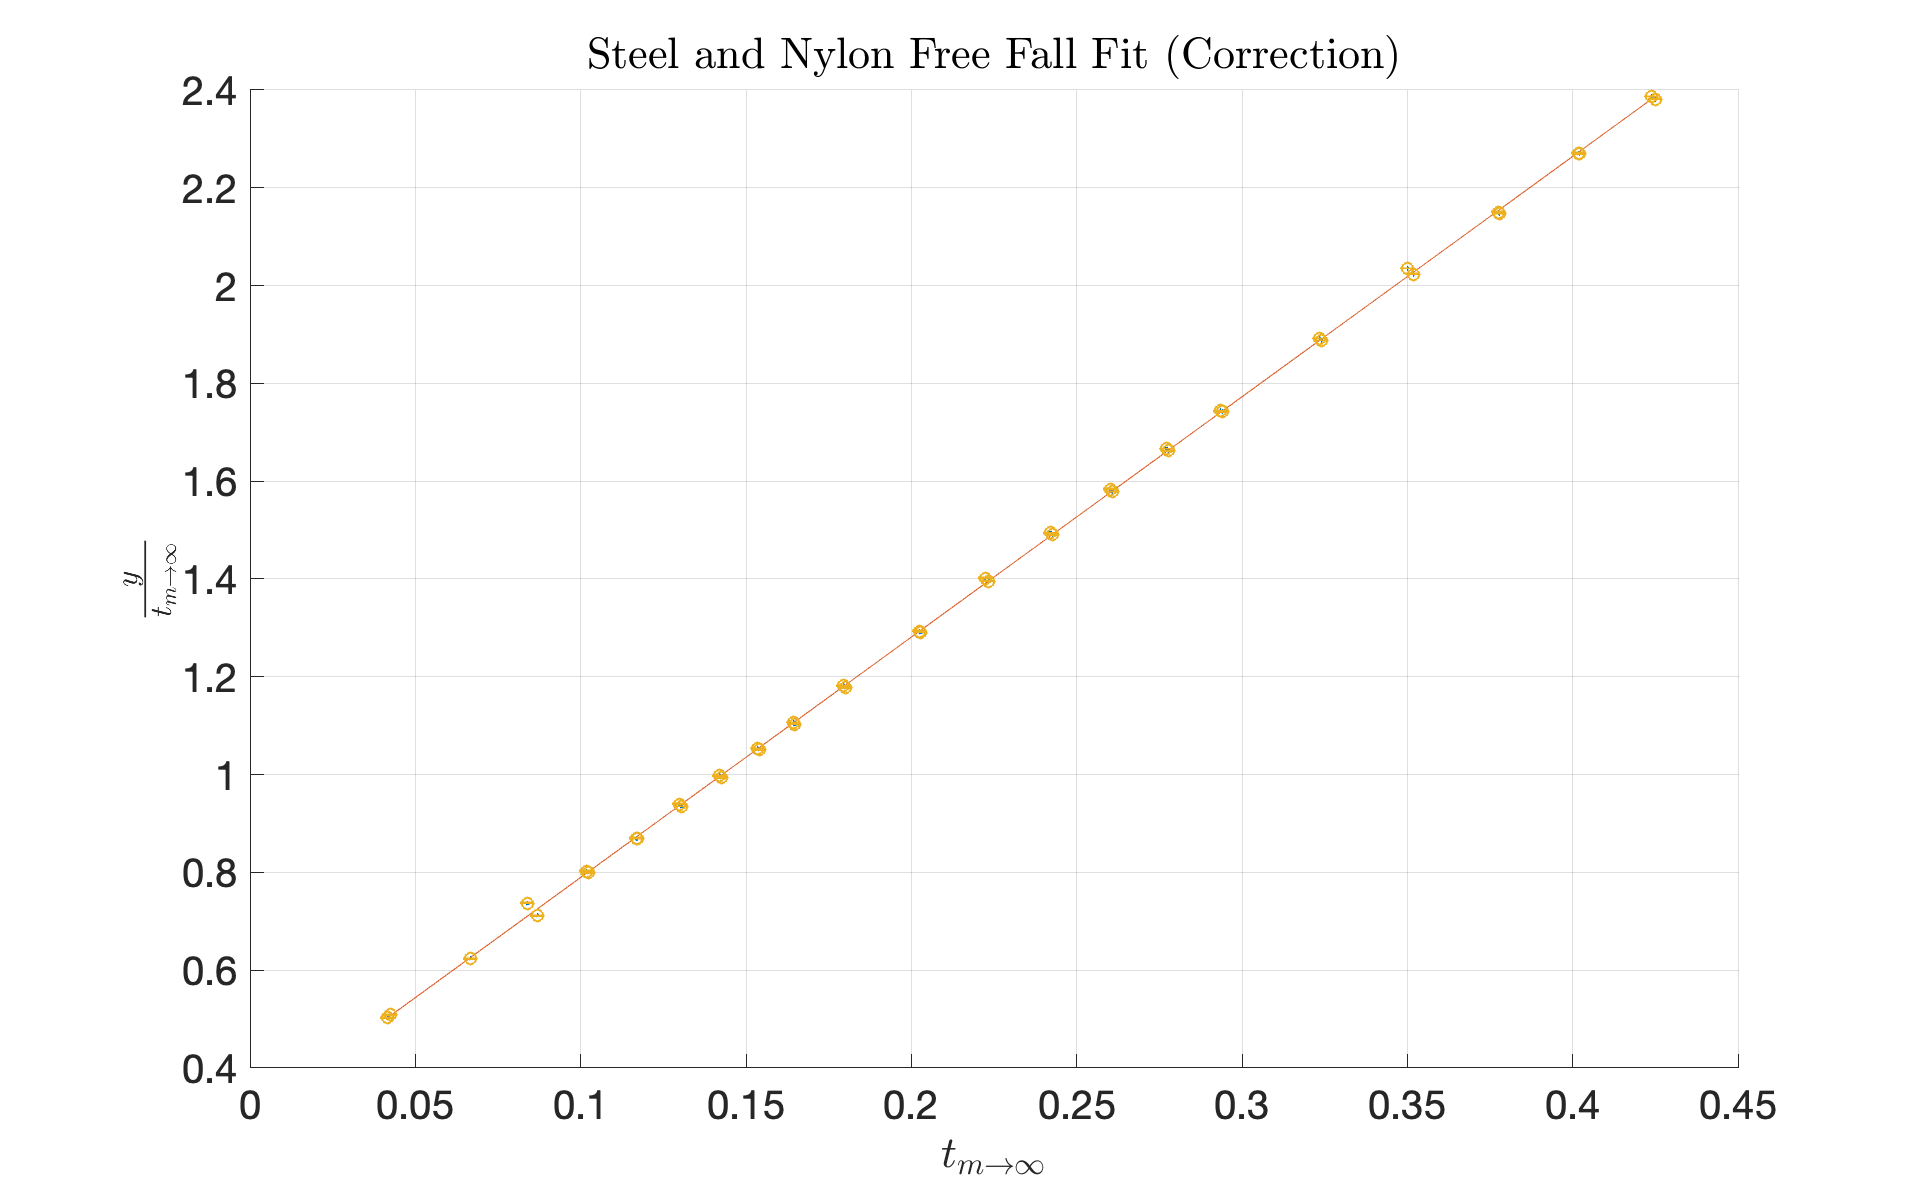


sse = -1.*sse;
[px,py] = findpeaks(sse,del);
del_best = py;
dydt = y./t_inf + del_best./t_inf;
p = getparams(t_inf,dydt,dydt_err,del_best);
yp = p.b.*t_inf + p.a;

figure(5)
set(gcf,'Units','Normalized','Position',[0.5 0.05 0.5 0.5])
scatter(t_inf,dydt,2)
hold on
plot(t_inf,yp)
xlabel('$t_{m \rightarrow \infty}$','Interpreter','latex')
ylabel('$\frac{y}{t_{m \rightarrow \infty}}$',...
    'Interpreter','latex')
title('Steel and Nylon Free Fall Fit (Correction)',...
    'Interpreter','latex')
set(gca,'FontSize',20) 
grid on
errorbar(t_inf,dydt,dydt_err,'o');
hold off

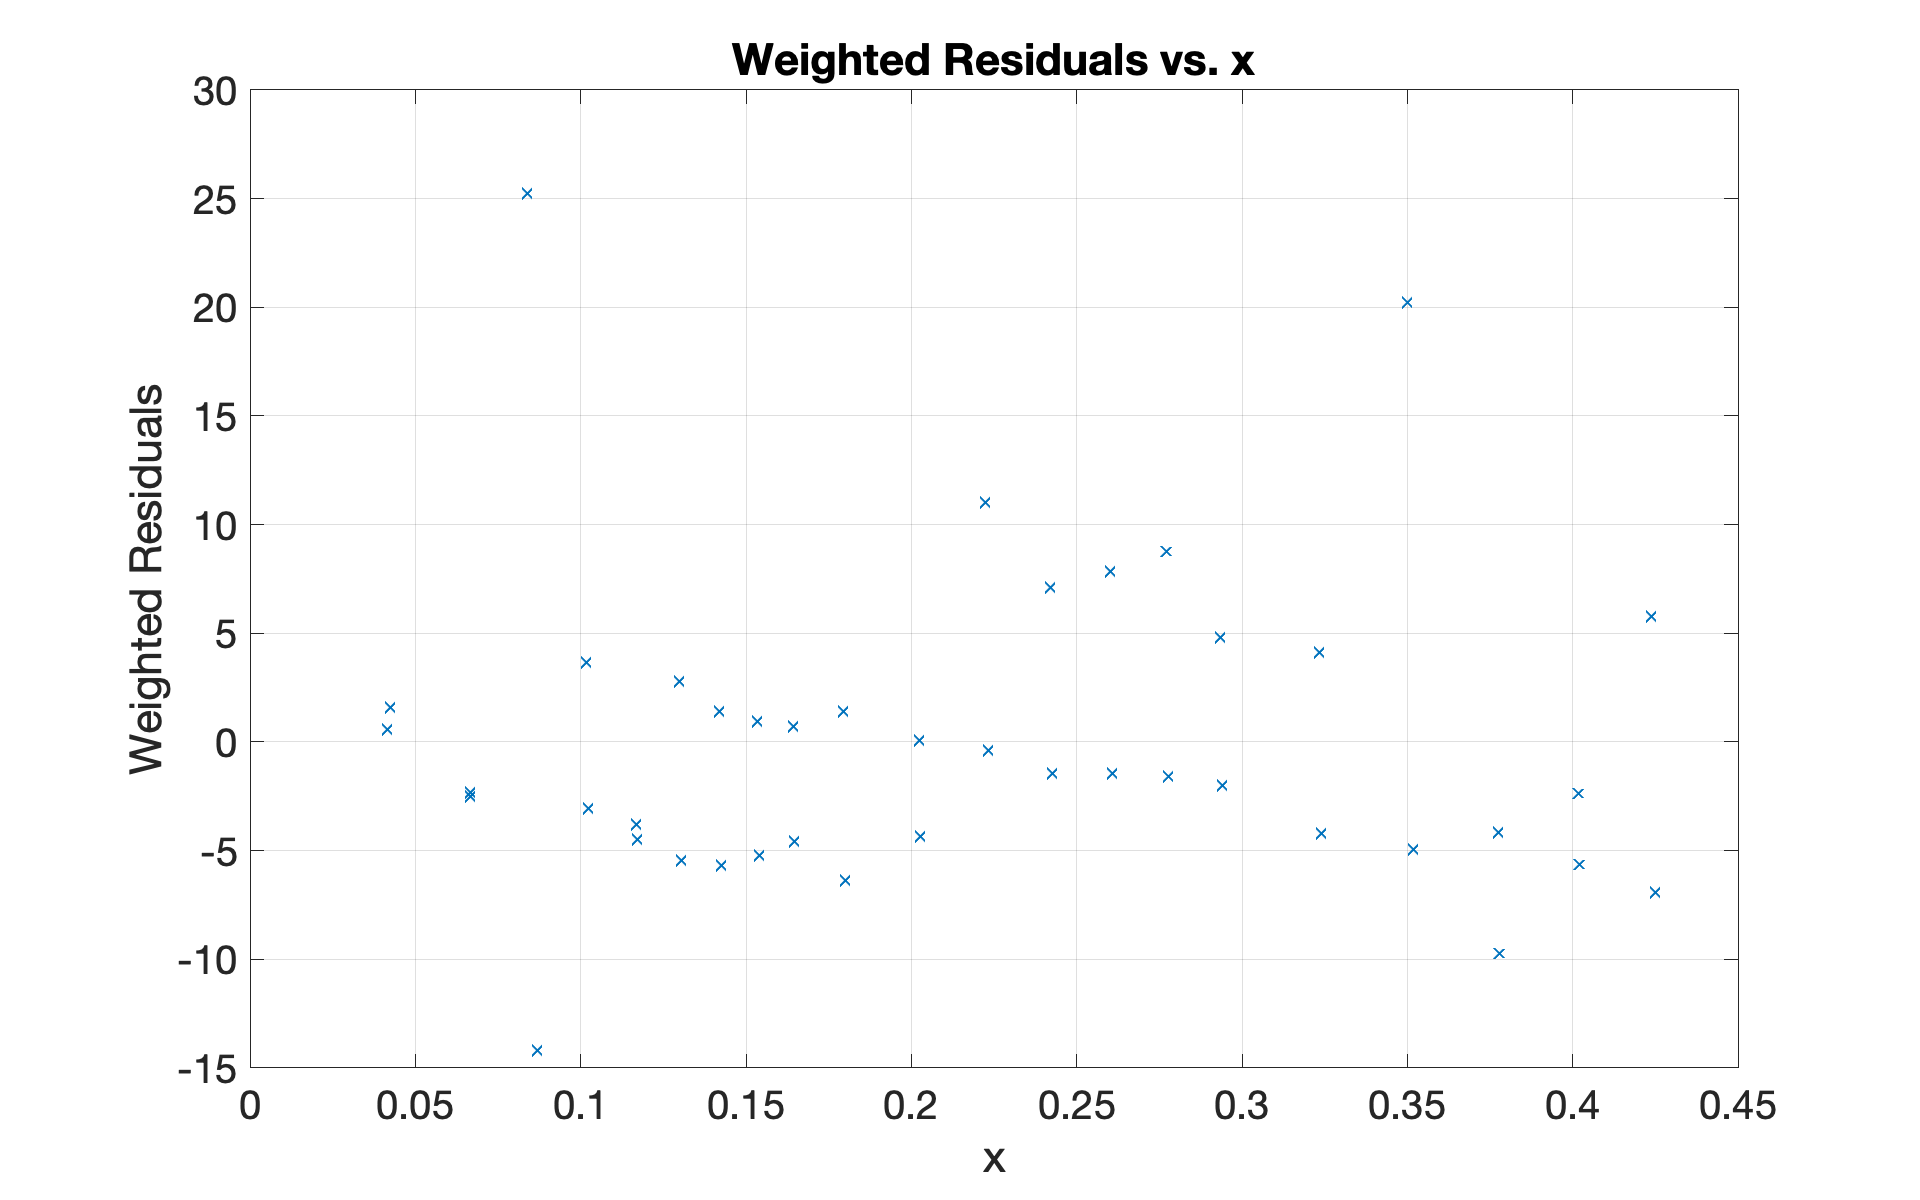



figure(6)
set(gcf,'Units','Normalized','Position',[0.65 0.5 0.5 0.5])
plot(t_inf(1:length(p.res),:), (p.res), 'x')
title('Weighted Residuals vs. x')
xlabel('x')
ylabel('Weighted Residuals')
set(gca,'FontSize',20) 
grid on

fprintf('\n\nBest Value of del is: del = %.5f\n',py)



Best Value of del is: del = 0.01152


fprintf('Sum of Chi Squared = %.0f \n',-px) 

Sum of Chi Squared = 2137 


fprintf('Reduced Chi Squared = %.1f \n',p.r_chi)

Reduced Chi Squared = 53.4 


fprintf('Calculated value of g = %.5f +/- %.5f m/s^2 \n',...
    2*p.b,2*p.b_err)

Calculated value of g = 9.82940 +/- 0.00238 m/s^2 


fprintf('Calculated value of V0 = %.5f +/- %.5f m/s \n',...
    p.a,p.a_err)

Calculated value of V0 = 0.29827 +/- 0.00031 m/s 


function chival = getSSE(x,y,sig_y,del)
    [~, gof, ~] = fit(x, y,'poly1', 'Weights',(1./sig_y).^2);
    sprintf(['Chi Squared Fit --- del = %.4f'...
        ' --- SSE = %.0f\n'],del,gof.sse);
    chival = gof.sse;
end

function p = getparams(x,y,sig_y,del)
    [fitobj, gof, outp] = fit(x, y,'poly1', ...
        'Weights',(1./sig_y).^2);
    sprintf(['Chi Squared Fit --- del = %.5f'...
        ' --- SSE = %.0f\n'],del,gof.sse);
    p.b = fitobj.p1;
    p.a = fitobj.p2;
    p.res = outp.residuals;
    p.outp = outp;
    p.fitobj = fitobj;
    error_matrix = inv(outp.Jacobian'*outp.Jacobian); 
    dcov =  diag(error_matrix);
    unc = sqrt(dcov)';
    p.b_err = unc(1);
    p.a_err = unc(2);
    p.r_chi = gof.sse/gof.dfe;
end

function [t_nylon,t_steel,y,y_err] = ...
    drop(delete,t_nylon,t_steel,y,y_err)
    t_nylon(delete,:) = [];
    t_steel(delete,:) = [];
    y(delete,:) = [];
    y_err(delete,:) = [];
end